clf
im = imread('images/garzweiler/2020-12-31.png');
im = imread('images/alberta/mining_2020.png');
im = imread('images/grasberg/2020-12-31.png');
% im = imread('images/chuquicamata/2020-12-31.png');
im = double(imresize(im, 0.25));
n_groups = 2;
[newim, means, p] = kmeansHSV(im, n_groups);

ans =    282   369     3


ans =    282   369     3


ans = 282

ans = 369

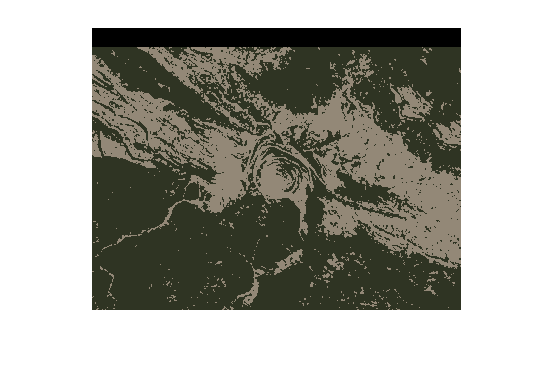

imshow(newim)

function [newimg, means, p1] = kmeansHSV(img, num)
    hsv1 = rgb2hsv(img);
    h1 = hsv1(:,:,1);
    h1 = reshape(h1.',1,[]);
    s1 = hsv1(:,:,2);
    s1 = reshape(s1.',1,[]);
    v1 = hsv1(:,:,3);
    v1 = reshape(v1.',1,[]);

    mean_idxs = randperm(length(h1), num);
    means = [h1(mean_idxs); s1(mean_idxs); v1(mean_idxs)]';
    p1 = zeros(size(h1));
    
    for i=1:20
        for j=1:length(p1)
            dists = sqrt((means(:,1) - h1(j)).^2 ...
                + (means(:,2) - s1(j)).^2 ...
                + (means(:,3) - v1(j)).^2);
            [maxd, idx] = min(dists);
            p1(j) = idx;
        end 
        for k=1:num
            group = (p1==k);
            % sum(group)
            sum_h = sum(group.*h1);
            sum_s = sum(group.*s1);
            sum_v = sum(group.*v1);
            means(k,1) = sum_h./nnz(group);
            means(k,2) = sum_s./nnz(group);
            means(k,3) = sum_v./nnz(group);
            % means
        end
    end
    means = sortrows(means,1);
    for j=1:length(p1)
        dists = sqrt((means(:,1) - h1(j)).^2 ...
            + (means(:,2) - s1(j)).^2 ...
            + (means(:,3) - v1(j)).^2);
        [maxd, idx] = min(dists);
        p1(j) = idx;
    end 

    h1new = zeros(size(h1));
    s1new = zeros(size(s1));
    v1new = zeros(size(v1));
    for k=1:length(means(:,1))
        group = (p1==k);
        h1new = h1new + group.*means(k,1);
        s1new = s1new + group.*means(k,2);
        v1new = v1new + group.*means(k,3);
    end
    hsv1new = zeros(size(hsv1));
    size(hsv1new)
    size(hsv1)
    size(hsv1, 1)
    size(hsv1, 2)
    for i=i:size(hsv1, 1)
        for j=1:size(hsv1, 2)
            hsv1new(i,j,1);
            h1new( (i-1)*size(hsv1,2)+j );
            hsv1new(i,j,1) = h1new( (i-1)*size(hsv1,2)+j );
            hsv1new(i,j,2) = s1new( (i-1)*size(hsv1,2)+j );
            hsv1new(i,j,3) = v1new( (i-1)*size(hsv1,2)+j );
        end
    end
    newimg = uint8(hsv2rgb(hsv1new));
end
